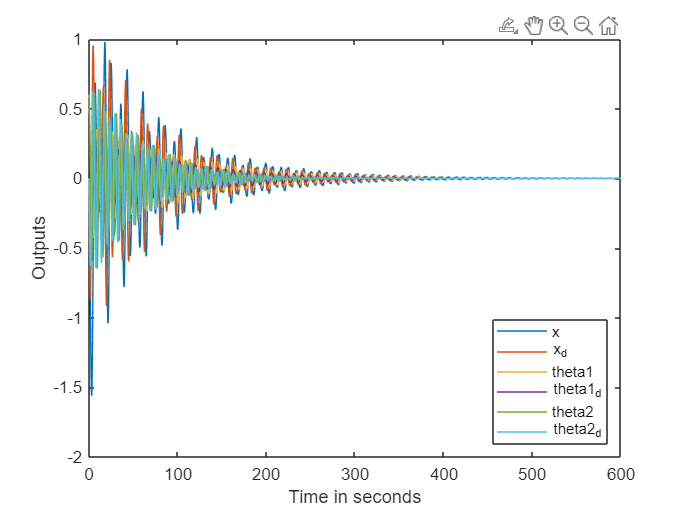

t_span = 0:0.01:600;
x_0 = [0; 0; 0.5; 0; 0.6; 0];
[ts, x_dots] = ode45(@non_lin_sys, t_span, x_0);
figure
plot(ts, x_dots)
xlabel('Time in seconds')
ylabel('Outputs')
legend()
legend({'x','x_d', 'theta1', 'theta1_d', 'theta2', 'theta2_d'},'Location','southeast')

function x_dot = non_lin_sys(t1, x)
    x_dot = zeros(6,1);

    % Declaring the values of system variables
    M_val = 1000;
    m1_val = 100;
    m2_val = 100;
    l1_val = 20;
    l2_val = 10;
    g_val = 9.81;
    
    % Declaring the A matrix of the system
    A_val = [0 1 0 0 0 0;
         0 0 -(m1_val*g_val)/M_val 0 -(m2_val*g_val)/M_val 0;
         0 0 0 1 0 0;
         0 0 -((M_val+m1_val)*g_val/(M_val*l1_val)) 0 -(m2_val*g_val)/(M_val*l1_val) 0;
         0 0 0 0 0 1;
         0 0 -(m1_val*g_val)/(M_val*l2_val) 0 -((M_val+m2_val)*g_val/(M_val*l2_val)) 0];
    
    % Declaring the B matrix of the system
    B_val = [0; 1/M_val; 0; 1/(M_val*l1_val); 0; 1/(M_val*l2_val)];
    
    % Defining the Q and R matrices for LQR controller
    Q = [10  0  0  0  0  0;
         0  10  0  0  0  0;
         0   0 100 0  0  0;
         0   0  0  1  0  0;
         0   0  0  0 100 0;
         0   0  0  0  0  1];
    
    R = 0.001;
    K = lqr(A_val,B_val,Q,R);
    fb = -K*x;
    
    % State x_dot_1 is x_2
    x_dot(1) = x(2);
    % State x_dot_2 is 
    x_dot(2) = (fb - (g_val/2)*(m1_val*sin(2*x(3)) + m2_val*sin(2*x(5))) - (m1_val*l1_val*(x(4)^2)*sin(x(3))) - (m2_val*l2_val*(x(6)^2)*sin(x(5)))) / (M_val+m1_val*((sin(x(3)))^2)+m2_val*((sin(x(5)))^2));
    % State x_dot_3 is theta 1
    x_dot(3) = x(4);
    % State x_dot_4 is theta1 dot
    x_dot(4) = (x_dot(2)*cos(x(3)) - g_val*(sin(x(3))))/l1_val';
    % State x_dot_5 is theta2
    x_dot(5) = x(6);
    % State x_dot_6 is theta2 dot
    x_dot(6) = (x_dot(2)*cos(x(5)) - g_val*(sin(x(5))))/l2_val;

end